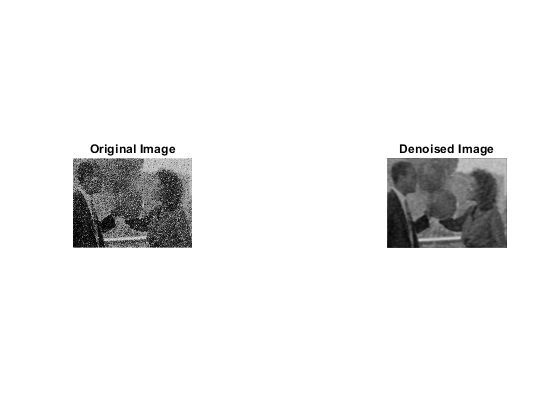

% Image Denoising using Frequency Domain Filters
% This script demonstrates denoising an image using a low-pass filter in the frequency domain

% Clear workspace and close all figures
clear all;
close all;
clc;

% Read and prepare the image
img = imread('R.png'); % Load a standard test image
if size(img, 3) == 3
    img = rgb2gray(img); % Convert to grayscale if RGB
end
img = im2double(img); % Convert to double precision


% Perform FFT to move to frequency domain
fft_img = fft2(img);
fft_shifted = fftshift(fft_img); % Shift zero frequency to center

% Create a low-pass Butterworth filter
[M, N] = size(img);
D0 = 30; % Cutoff frequency (adjustable)
n = 2; % Filter order
[X, Y] = meshgrid(1:N, 1:M);
center = [M/2, N/2];
D = sqrt((X - center(2)).^2 + (Y - center(1)).^2);
H = 1 ./ (1 + (D ./ D0).^(2*n)); % Butterworth low-pass filter

% Apply filter in frequency domain
filtered_fft = fft_shifted .* H;

% Inverse FFT to return to spatial domain
ifft_shifted = ifftshift(filtered_fft);
denoised_img = real(ifft2(ifft_shifted));

% Display results
figure('Name', 'Image Denoising using Frequency Domain Filter', 'NumberTitle', 'off');

subplot(1, 3, 1);
imshow(img);
title('Original Image');


subplot(1, 3, 3);
imshow(denoised_img);
title('Denoised Image');


% Calculate and display PSNR
psnr_value = psnr(denoised_img, img);
fprintf('PSNR of denoised image: %.2f dB\n', psnr_value);

PSNR of denoised image: 19.20 dB



% Save the denoised image
imwrite(denoised_img, 'denoised_image.png');